Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       10.54% |       39.14% |       2.1794 |       1.8354 |          0.0010 |
|      50 |          50 |       00:04:29 |       49.48% |       49.47% |       1.3715 |       1.3700 |          0.0010 |
|======================================================================================================================|
Training finished: Max epochs completed.


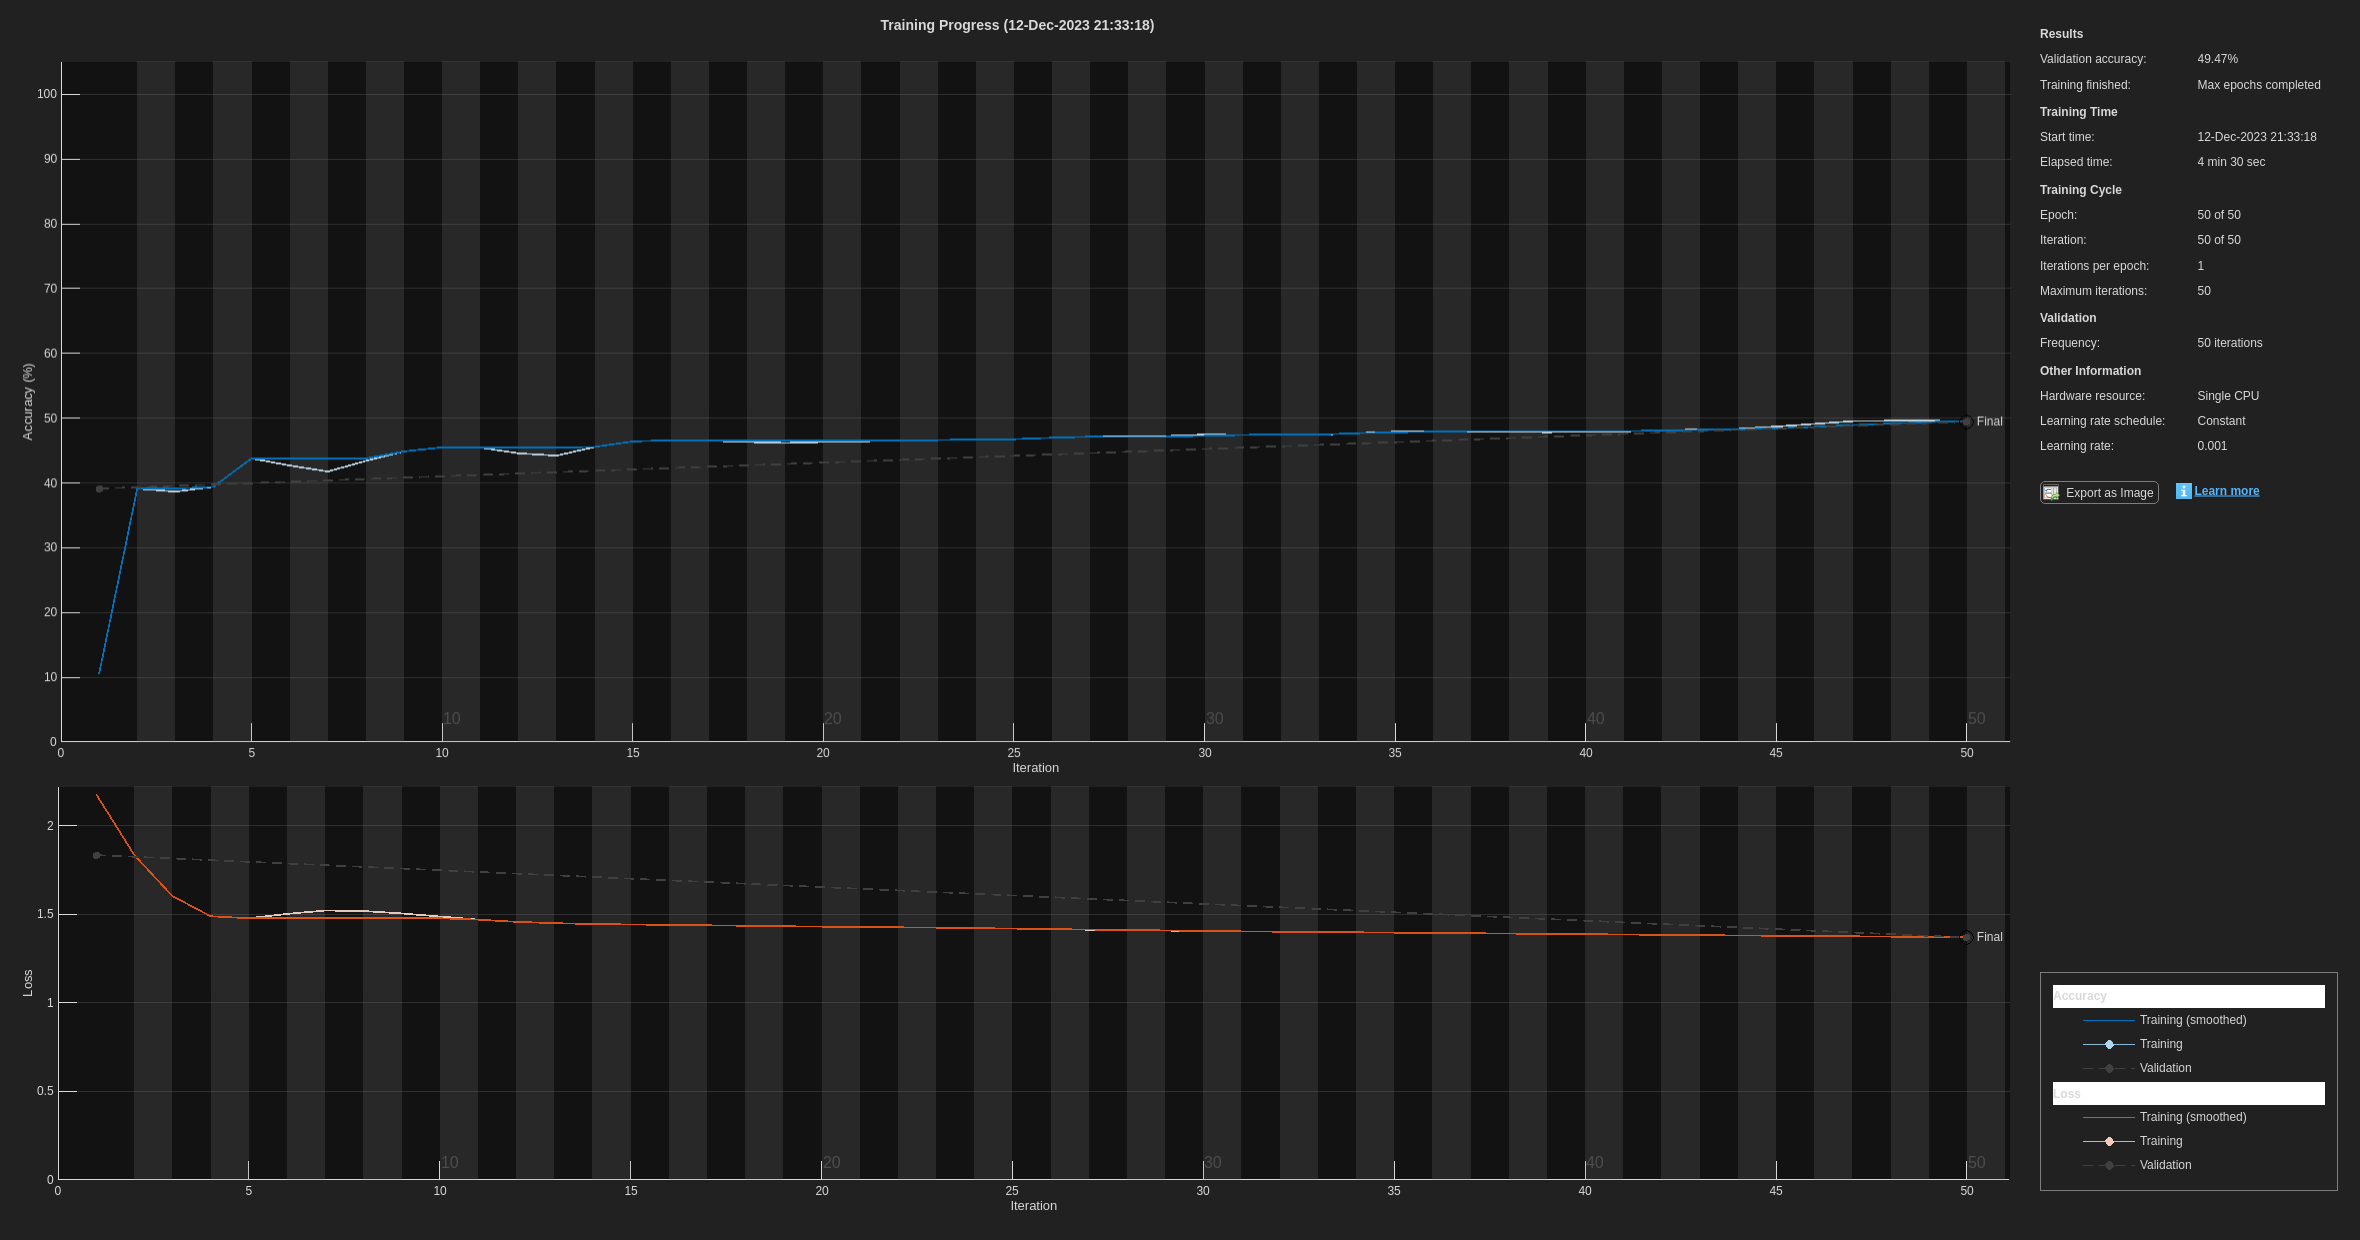

clear all;
load sequence_Hawaiian_train.mat;

time_series_data = sequence;

% Assuming you have a 1D time series data named 'time_series_data'
sequence_length = 5;  % Length of input sequences
num_samples = length(time_series_data) - sequence_length;

% Create sequences
X = zeros(sequence_length, num_samples);
y = zeros(1, num_samples);

for i = 1:num_samples
    X(:, i) = time_series_data(i:i+sequence_length-1);
    y(i) = time_series_data(i+sequence_length);
end

% Reshape the input data for LSTM
X = permute(X, [1, 2, 3]);  % [10, num_samples, 1]

% Build the modified LSTM model with 9 output neurons
numUnits = 200;
numClasses = 9;  % Number of output classes

layers = [
    sequenceInputLayer(sequence_length)
    lstmLayer(numUnits, 'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

% Training options (modify as needed)
options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'ValidationData', {X, categorical(y)}, ...  % Use categorical labels for classification
    'Plots', 'training-progress');

% Train the modified LSTM model
net = trainNetwork(X, categorical(y), layers, options);

dataset = [1; 2; 3; 4; 5;];
net.resetState;
sequenceLength = initializeSymbolMachine('sequence_Hawaiian_test.mat',0);

Initialized Symbol Machine for sequence_Hawaiian_test.mat, which contains 5654 symbols.
Use symbolMachine.m to make forecasts.



probs = [1/9 1/9 1/9 1/9 1/9 1/9 1/9 1/9 1/9];
for ii = 1:sequence_length
    [dataset(ii), penalty] = symbolMachine(probs);
end
for jj = sequence_length+1:sequenceLength
    [net, probs] = predictAndUpdateState(net, dataset);
    for ii = 1 : (sequence_length-1)
        dataset(ii) = dataset(ii+1);
    end
    [dataset(sequence_length), penalty] = symbolMachine(probs);
end
reportSymbolMachine;

SYMBOL MACHINE REPORT (EMAIL TO PROF WAKIN FOR LEADERBOARD)
Processed 5654 out of 5654 symbols in sequence_Hawaiian_test.mat.
Total penalty: 11012.248 bits (1.9477 bits per symbol).
       64 probabilities forecasted between 0.0000 (Inf bits) and 0.0039 (8 bits); actual occurrence rate 0.0000.
     3539 probabilities forecasted between 0.0039 (8 bits) and 0.0078 (7 bits); actual occurrence rate 0.0059.
     6978 probabilities forecasted between 0.0078 (7 bits) and 0.0156 (6 bits); actual occurrence rate 0.0100.
    12887 probabilities forecasted between 0.0156 (6 bits) and 0.0312 (5 bits); actual occurrence rate 0.0220.
    12944 probabilities forecasted between 0.0312 (5 bits) and 0.0625 (4 bits); actual occurrence rate 0.0337.
     2932 probabilities forecasted between 0.0625 (4 bits) and 0.1250 (3 bits); actual occurrence rate 0.1044.
     1431 probabilities forecasted between 0.1250 (3 bits) and 0.2500 (2 bits); actual occurrence rate 0.2103.
     8226 probabilities forecasted betw